# Support structure cost - Live script

- Imports sea depth (bathymetry) data

- Sets turbines to random posittions

- Calculates the water depth at each point

- Uses design variables for depths ranges each support type is used in to set support type for each turbine

- Calcuates the cost of support for each turbine 

% importing bathymetry data, setting random turbine coordinates, and
% calculating water depth at each point
[A,R] = readgeoraster('hsb.tif','OutputType','double');
latlim = R.LatitudeLimits;
longlim = R.LongitudeLimits;

info = geotiffinfo('hsb.tif');
height = info.Height; % Integer indicating the height of the image in pixels
width = info.Width; % Integer indicating the width of the image in pixels
x = 1:width;
y = 1:height;

max_lat = 54; 
min_lat = 53.7; 
max_long = 2.8; 
min_long = 2.1;

TCA = zeros([300,4]);%main turbine cost array 

for t=1:300 %for turbine 1 - turbine 300
    
    % set y/longtitude coord 
    TCA(t,2)= min_long + (max_long-min_long).*rand();
    
    % set x/latitide coord
    TCA(t,1)= min_lat + (max_lat-min_lat).*rand();
    
end

TCA

TCA =    53.9717    2.6703         0         0
   53.9740    2.1889         0         0
   53.7293    2.5427         0         0
   53.8641    2.2949         0         0
   53.9895    2.7703         0         0
   53.9912    2.2103         0         0
   53.8456    2.7700         0         0
   53.7426    2.6602         0         0
   53.9747    2.3952         0         0
   53.9878    2.6545         0         0



[rows,cols] = meshgrid(1:height,1:width);
[ADlat,ADlon] = pix2latlon(info.RefMatrix, rows, cols);
Idub=A;
% Interpolate meshgrid of bathymetry data to get water depths at each
% turbine location
TCA(:,3) = interp2(ADlat, ADlon, Idub.', TCA(:,1), TCA(:,2)) % X, Y (not in same order as lat long btw)

TCA =    53.9717    2.6703  -42.8227         0
   53.9740    2.1889  -37.8756         0
   53.7293    2.5427  -29.0000         0
   53.8641    2.2949  -33.8755         0
   53.9895    2.7703  -40.9720         0
   53.9912    2.2103  -64.6707         0
   53.8456    2.7700  -33.1681         0
   53.7426    2.6602  -36.2692         0
   53.9747    2.3952  -61.2989         0
   53.9878    2.6545  -41.5796         0


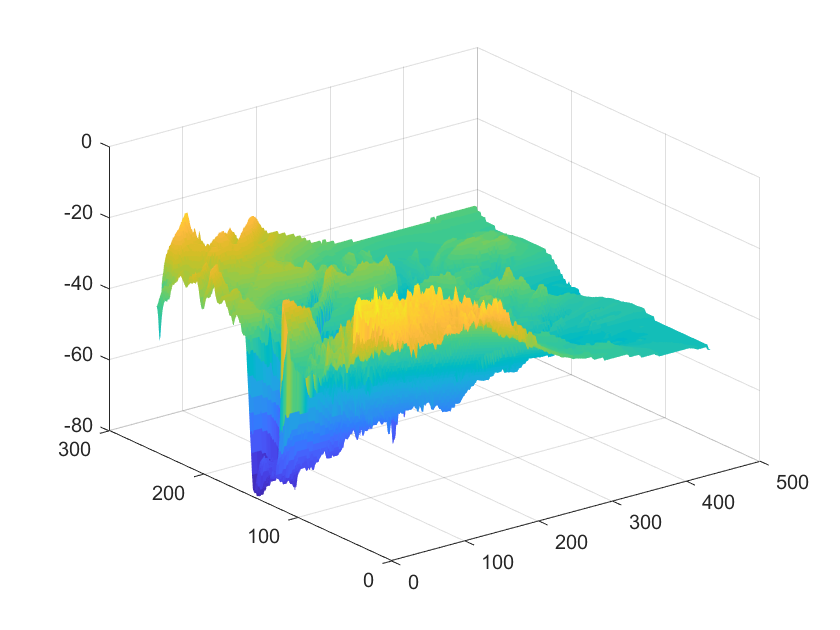

surf(Idub, 'edgecolor', 'none'); colormap(parula(256))

then needs to calculate support structure cost - dependant on water depth 

%"design variables" to optimise each loop = cut off depths for what support
%structure used. no over lap beween depths at which each support type is
%used
mp_limit_var = -30; 
j_limit_var = -80;  %number regarding to sea depth

%split TCA based on depth values, to get seperate arrays of depths for
%different turbine types
mp_tca = TCA(TCA(:,3)>=mp_limit_var,:) 

mp_tca =    53.7293    2.5427  -29.0000         0
   53.7107    2.5590  -29.0000         0
   53.7514    2.5588  -29.9337         0
   53.7139    2.2938  -30.0000         0
   53.7951    2.5864  -29.3312         0
   53.7488    2.5586  -29.6487         0
   53.7671    2.5097  -28.1750         0
   53.7416    2.4831  -28.0000         0
   53.7731    2.6700  -30.0000         0
   53.7162    2.1531  -24.6156         0


j_tca = TCA(TCA(:,3)>=j_limit_var,:) 

j_tca =    53.9717    2.6703  -42.8227         0
   53.9740    2.1889  -37.8756         0
   53.7293    2.5427  -29.0000         0
   53.8641    2.2949  -33.8755         0
   53.9895    2.7703  -40.9720         0
   53.9912    2.2103  -64.6707         0
   53.8456    2.7700  -33.1681         0
   53.7426    2.6602  -36.2692         0
   53.9747    2.3952  -61.2989         0
   53.9878    2.6545  -41.5796         0



%cost of support types - from minimalistic cost model 
gp = 6; %installed generator power in MW (6MW used on site)
c_t = 1.25*(-0.15+0.92*gp); %cost of wind turbine

%support structure cost equations (for reference, not used in code)
d = 25; %water depth in m
c_mp = (gp*(d*d +100*d +1500))/7500; %monopile
c_j = (gp*(0.5*(d*d)-35*d+2500))/7500; %jacket support structure

mpd = abs(mp_tca(:,3)); %monopile depth
mp_tca(:,4) = (gp*(mpd.^2 +100*mpd +1500))/7500; % cost of monopile support in million euros

%total monopile turbine support costs
tot_mp = sum(mp_tca(:,4),"all");

jd = abs(j_tca(:,3)); %jacket depth
j_tca(:,4) = (gp*(0.5*(jd.^2)-35*jd+2500))/7500 %jacket support structure in million euros

j_tca =    53.9717    2.6703  -42.8227    1.5345
   53.9740    2.1889  -37.8756    1.5133
   53.7293    2.5427  -29.0000    1.5244
   53.8641    2.2949  -33.8755    1.5105
   53.9895    2.7703  -40.9720    1.5243
   53.9912    2.2103  -64.6707    1.8621
   53.8456    2.7700  -33.1681    1.5113
   53.7426    2.6602  -36.2692    1.5106
   53.9747    2.3952  -61.2989    1.7867
   53.9878    2.6545  -41.5796    1.5273



% total jacket turbine support cost
tot_j = sum(j_tca(:,4),"all");


%  Total support structure cost (in million euros)
tot_support_cost = tot_mp + tot_j

tot_support_cost = 759.0105